# Video Pre-Processing & Draw Bounding Box - Test on Full Video

**Aim: **Build on from "Video Pre-Processing Workflow - Test Concept" ***(file:*** ***preprocessing_workflow_InitialTEST.mlx)****. *Will now attempt to run code on a full video. Then, will try to recreate video with bounded drops.

**Summary**: Starting with a video (.avi), individual frames are extracted and stored in a temporary folder. Then, loop through each individual frame for image processing and bounding boxes are overlaid onto orginal image frame. The overlaid images will be saved to the same temporary folder and replace the original image frames. 

**User notes: **

This script is based on the video: **SO5_17umL-13Wat_umL-10kfps x4mag_sh50_C001H001S0016.avi** 

There are also accompanying function files: 

- ***extractVidFrames.m***

- ***vidFramePreprocess.m***

- ***createVid.m***

If you would like to run the script, please ensure the video & files is in the same directory as this script. Link to the video file can be found on github. 

**Log:** 

**12-Jan-2020; SWC**. Completed code - looping operation worked! Computational time seems reasonable. Next steps: to remove i) bounding boxes outside main channel and ii) small noise objects picked up in some frames (maybe try 'remove if area < x). Check when will drops be classified as doublet! crop bounding boxes and save as individual images.

**17-Jan-2020; SWC**. Test on new video: SO5_17umL-13Wat_umL-10kfps x4mag_sh50_C001H001S0007.avi (video not linked, but available at Nina's shared drive); added code to combine frames into a full video [function file: createVid.m].

**26-Jan-2020; SWC**. Test on: SO5cSt 16uL_15 uL TRITON_0.5 mM 034.avi

**27-Jan-2020; SWC**. tested with v2.0 of vidPreprocess function. 

Test on: SO5cSt 16uL_15 uL TRITON_0.5 mM 034.avi (Output files: test003; test_out003)

Test on: SO5cSt 12uL_23 uL SDS_10 mM 02.avi (Output files: test004; test_out004)

**2-Feb-2021; SWC.** Review code and tidy notes. Initial commit to github.

**9-Feb-2021; SWC.** Test on dark drops video: 52%Gl_W_0.003_Ink_SO_SPAN80_0.003_2kfps_.avi. Observation of the day: Image manipulation output depends on the image class during processing operation --> need to double check, particularly image subtraction part.

**10-Feb-2021; SWC.** data class issue resolved. continue to test on dark drops video; will try with more complex background generation method; preliminary test on 1 video frame looks promising in terms of algorithm's versatility, so will see how it performs on full video. 

background generation quality is ok, but ultimately detected region still affected by selection of a suitable treshold value

clear all 
close all 
clc 

##  1) Load Video

% vid_file_name = 'SO5_17umL-13Wat_umL-10kfps x4mag_sh50_C001H001S0016.avi'; %<-------- user-defined input!!
vid_file_name = '52%Gl_W_0.003_Ink_SO_SPAN80_0.003_2kfps_.avi';
vid = VideoReader(vid_file_name); %read video
% make sure video is in the same path as codes!!
totframes = vid.NumFrames %check total num of frames in video

totframes = 5741

## 2a) Background Generation - Use Median of Frames

tic
n = 200;    % number of frames to use for background generation  <-------- user-defined input!!
idx = round(linspace(1,totframes,n)); %vector of index of frame number to be extracted

frameMat = []; 

% for loop to create matrix of frames - for generating background image
for i=1:numel(idx)
    frame = read(vid,idx(i)); 
    frameMat = cat(3,frameMat,frame);
end


med_pix = median(frameMat,3); %compute median of each pixel across all frames in matrix
toc

Elapsed time is 6.976514 seconds.


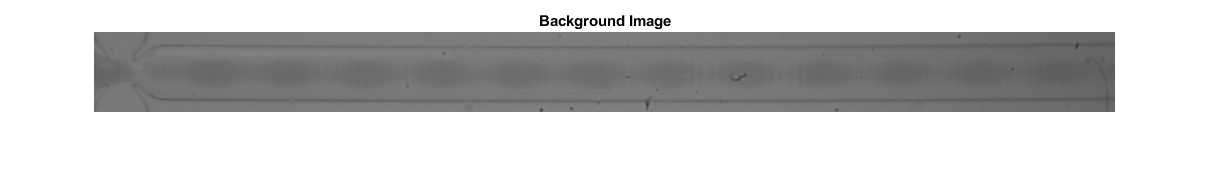


%show generated background 
imshow(med_pix); title("Background Image")

## 2b) Background Generation - Use 'Complex' Method

tic;
n = 50;    % number of frames to use for background generation

idx = randperm(totframes,n); %vector of index of frame number to be extracted; randomly selected
frameMat = [];

% for loop to create matrix of frames - for generating background image
for j=1:numel(idx)
    frame = read(vid,idx(j));
    frameMat = cat(3,frameMat,frame);
end

bg = mean(frameMat,3,'native'); %compute mean value of each pixel across all frames in matrix

Imin = double(min(bg,[],'all'));
Imax = double(max(bg,[],'all'));

% figure; imshow(bg)


f = randperm(totframes,n);

Al2 = (245*(double(bg)-Imin))/(Imax-Imin) + 10;
R = bg;

for nf = 1:length(f)
    F = read(vid, f(nf));
    Fl2 = (245*(double(F)-Imin))/(Imax-Imin) + 10;
    
    D = 255.* Fl2 ./ Al2;
    D(Al2 <= 0 | Fl2 > Al2) = 255;
    D(Fl2 < 0) = 0;
%     D = mat2gray(D);
    D = rescale(D);
    
    B1 = imbinarize(D);
    B2 = imcomplement(B1);
    
    B2_fill = bwconvhull(B2,'object');
    B2_fill = bwareaopen(B2_fill,1000);
    A2 = regionprops('table',B2_fill,'BoundingBox');
    se = strel('disk', round(0.2*min(A2.BoundingBox(:,3))));
    B2_dilate = imdilate(B2_fill,se);
    M2 = uint8(double(R).*double(B2_dilate));
    
    B1_dilate = imcomplement(B2_dilate);
    M1 = uint8(double(B1_dilate).*double(F));
    
    R = M1+M2;
    
    %     figure; imshow(M1); figure; imshow(M2);
    %     figure; imshow(R);
    
end
toc;

Elapsed time is 8.733535 seconds.


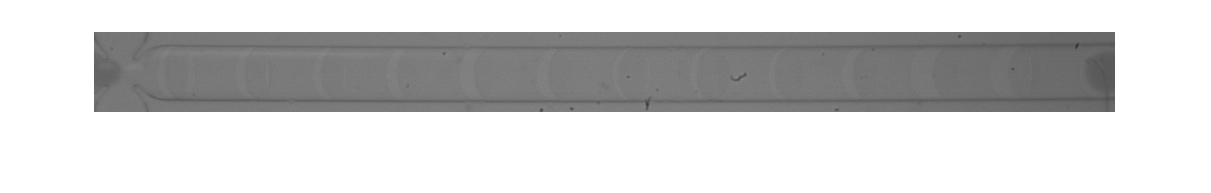


figure; imshow(R)

## 3) Extract Video Frames & Save in Temporary Folder 

**Accompanying function file: ***extractVidFrames.m*

*Note: if want to test code, check if the temporary subfolder already exists from previous runs. If so, delete subfolder from the shared drive first before running code.*

- Create temporary folder to store files

mkdir test003_darkdrops % have created 'test_0016' subfolder as example <-------- user-defined input!!
addpath test003_darkdrops % enable access to subfolder <-------- user-defined input!!

- Define user inputs for function

num_frames = totframes; % number of frames to extract from video <-------- user-defined input!!
file_path = 'test003_darkdrops\'; %folder to save images in <-------- user-defined input!!

- call function

extractVidFrames(vid_file_name, num_frames, file_path); %extracted video frames saved in temporary subfolder

## 4) Create Labelled Video Frames & Save in Temporary Folder 

**Accompanying function file**: *vidFramePreprocess.m*

*Note: will create a new sub-folder to store images with bounding boxes.*

framesBbox_folder = 'test003_darkdrops_Bbox';
mkdir(framesBbox_folder)
addpath(framesBbox_folder)

% define vidFramePreprocess function inputs
bg = R; %background image - generated earlier
t = 0.2; %treshold value <-------- user-defined input!!
foldername = 'test003_darkdrops_Bbox'; %<-------- user-defined input!!
minArea = 1000; % <-------- user-defined input!!
leadEdge = 140; % <-------- user-defined input!!

%access individual frames
frames_folder = dir('test003_darkdrops\*.jpg'); %<-------- user-defined input!!

tic
%loop through each frame in subfolder
for i = 1:numel(frames_folder)
    file = fullfile('test003_darkdrops',sprintf('%d.jpg',i));
    
    vidFramePreprocess(file, bg, t, minArea, leadEdge, foldername,i);
end
toc


Once loop operation finished, check temporary subfolder => should be able to see video frames with bounded drops. 

*Note-to-self (17-Jan, SWC): Using the video ****SO5_17umL-13Wat_umL-10kfps x4mag_sh50_C001H001S0007.avi**** with 1936 frames, took nearly an hour to complete loop on my laptop (relatively low computing power..). I suspect this will be quicker with  a more powerful laptop, but if just to test code, best change 'num_frames' in Section 3 above.*

## 5) Recreate video - with bounding boxes

**Accompanying function file***: createVid.m.*

tic
labelled_vid = createVid('lab-0016', vid.FrameRate, foldername, num_frames);  % <-------- user-defined input!!

Unrecognized function or variable 'foldername'.

% inputs: (name the file to be saved as, frame rate, total number of frames
% to create video)
toc

*Note-to-self (17-Jan, SWC): using video: ****SO5_17umL-13Wat_umL-10kfps x4mag_sh50_C001H001S0007.avi. ****created video from 1936 frames, just over 2 mins - not too bad.*